# STITCH anaysis on gata5 timecourse single-cell data

Note that this script only did a few custome edits based on the orignal script from Wagner et al., 2018 Create a 1x4 array to store single cell data each time point is stored in a field before loading the sparse matrix from 10x outputs. double click mmread in your folder to load the function, it is not built in in MatLab and can not be added using add-ons.

A = struct(...
    'ind', {1, 2, 3, 4}, ...
    'name', {'06hpf', '08hpf', '10hpf', '13hpf'}, ...
    'X', {mmread('6h_SCT.mtx'), mmread('8h_SCT.mtx'), ...
          mmread('10h_SCT.mtx'), mmread('13h_SCT.mtx')})

A = 1×4 struct array with fields:
    ind
    name
    X



for id = 1:length(A)
    fprintf('%d\n',id)
    disp(A(id))
end

1


     ind: 1
    name: '06hpf'
       X: [16341×879 double]



2


     ind: 2
    name: '08hpf'
       X: [16341×1467 double]



3


     ind: 3
    name: '10hpf'
       X: [16341×1407 double]



4


     ind: 4
    name: '13hpf'
       X: [16341×1605 double]




% Now you have a structured array, follow script_runSTITCH_Wagner2018.m

## (1) Add scTools functions to Matlab path

addpath('scTools')
addpath('scTools/stitch')
addpath('scTools/generic')

## (2) Perform total counts normalization

nTimePoints = length(A);
disp('Normalizing data...')

Normalizing data...


for j = 1:nTimePoints
    [A(j).X_norm, A(j).tot_counts] = get_normalized_counts(A(j).X);
end
disp('Done normalizing')

Done normalizing


## (5) Identify variable genes

Define settings used in Wagner et al. 2018. 

disp('Getting variable genes...')

Getting variable genes...


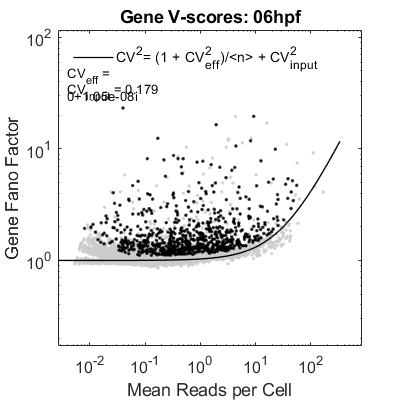

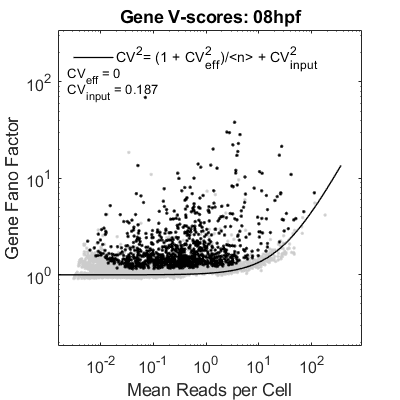

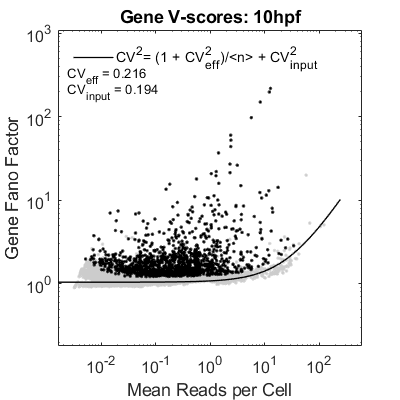

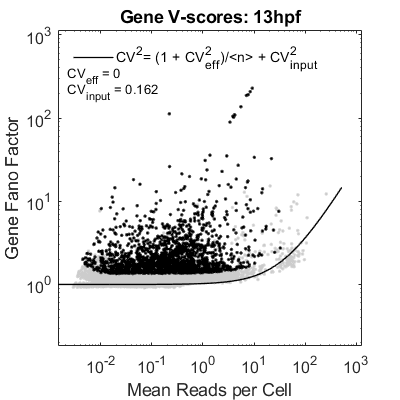

%CV_eff =   [0.60 0.40 0.40 0.40 0.40 0.40 0.40];
%CV_input = [0.20 0.15 0.15 0.20 0.22 0.22 0.22];
exclude_genes = {'cdk1','mcm2', 'mcm7','rrm2', 'cdc6', 'ccnf', ...
                 'cirbpb', 'rps27.1', 'rps8a', 'rpl26', 'rpl36a', ...
                 'rpl34', 'rpl13', 'rpl9', 'rpl11','rpl37', 'rps6', ...
                 'rpl10', 'rps3a', 'rpl31', 'rps14', 'rps15a', ...
                 'rps12', 'rpl12', 'rps13', 'hnrnpaba','hspd1', 'hspa9', 'rplp0', ...
                 'kif4','hmgb1b', 'hmgb3a', 'cdca4', 'ccnd1'};       
             
% import genesSCT.tsv as cell, text option cell array of character vectors                          
for j = 1:nTimePoints
    A(j).gene_ind = get_variable_genes(A(j), 'excludeGeneNames', exclude_genes, ...
                                        'allGeneNames', gene_names_all);
end

disp('Done identifying variable genes.')

Done identifying variable genes.


## (6) Calculate the STITCH graph

disp('Calculating STITCH graph...')

Calculating STITCH graph...


G = stitch_get_graph(A);

Building kNN graphs...
Done building kNN graph: 13hpf
Done building kNN graph: 10hpf
Done building kNN graph: 08hpf
Done building kNN graph: 06hpf
Done stitching: 10hpf->13hpf
Done stitching: 08hpf->10hpf
Done stitching: 06hpf->08hpf
Done merging
Filtering graph...
# starting nodes: 5358
# starting edges: 1759K
# nodes after distance filters: 5358
# edges after distance filters: 410K
# nodes after mutual edge filter: 5358
# edges after mutual edge filter: 274K
# nodes after k_final filter: 5358
# edges after k_final filter: 68K
# nodes in giant: 5304
# edges in giant: 68K
Done filtering


% export it as .dot file and use it as the input for gephi 
addpath('scTools/graphViz2Mat1')
graph_to_dot(adjacency(G), 'directed', 0, 'filename', 'timecourse_wt_SCT.dot')

% after installing gephi, got an error 'can not find Jave1.8 or higher'
% go to .\gephi\Gephi-0.9.2\etc
% change jkdhome path to jdkhome='C:\Program Files\Java\jdk-10.0.2'
% import .dot file, choose layout as 'ForceAltas2' if you don't change
% layout you will get a rectangle!!
% file > export> as .net file

## (7) Plot the STITCH graph using precomputed XY coordinates

XY = import_gephi_xy('timecourse_wt_SCT.net');
figure; stitch_plot_graph(G, XY)

h = figure(5)

h =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9800 0.9800 0.9800]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


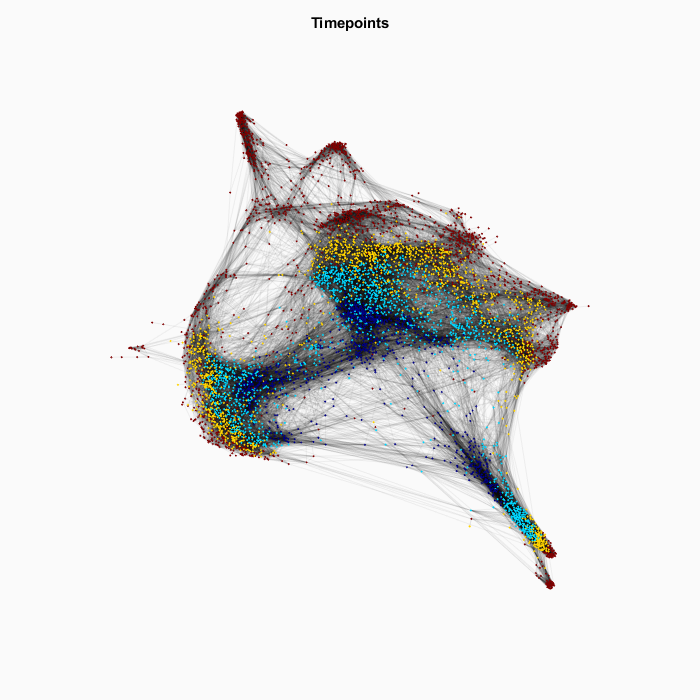

set(h,'Position',[100 100 700 700])
print(h, 'timecourse_regnor.png', '-dpng', '-r800')
print(h, 'timecourse_regnor.pdf', '-dpdf', '-r800')
savefig(h, 'timecourse_regnor.fig')

## （8）Plot cell type specific genes

%endoderm
pan_endoderm_gene = {'sox17','sox32','foxa2', 'cxcr4a','apela','prdx5'}
anterior_endoerm = {'nkx2.7', 'bcam', 'hbbe1.3'}
ventral_endoderm = {'ta', 'foxd5', 'onecut1', 'angptl3', 'limk2'}

for j = 1:length(overlapping_timecoures_genes)
    stitch_plot_graph(G, XY, A, gene_names_all, 'nodes', overlapping_timecoures_genes{j})
    h = figure(1)
    set(h,'Position',[100 100 500 600])
    p = strcat(overlapping_timecoures_genes{j}, '.png')
    q = strcat(overlapping_timecoures_genes{j}, '.pdf')
    r = strcat(overlapping_timecoures_genes{j}, '.fig')
    print(h, p,'-dpng','-r600')
    print(h, q,'-dpdf','-r600')
    savefig(h, r)
end


marker_gene = {'gata1a',  'cldng', 'gfi1aa','tal1', ... %%erythroid
               'foxj1a', 'hnf1bb', 'acy3.2','pax2a', ... %%pronephric
               'thbs3b', 'cthrc1a', 'twist1b', ... %%cpm1
               'junba', 'dhrs3a', 'nr2f1a', 'rbpms2b', ... %% atrium/fin 
               'foxa2', 'dap1b', 'prdx5', 'nkx2.7', 'bcam', ... %%dorsal/anterior endoderm
               'hand2', 'cdx4', 'cfd', 'emilin2b', 'ednraa' , 'msx3', ... %% ventral mesoderm
               'col15a1b', 'pknox2', 'foxf2a','pitx3', ... %% cpm2
               'gpx1a', 'snai1a', 'eve1', 'her7',  'cyp26a1', ... %%tail bud 
               'mef2ca', 'ttn.2', 'nkx2.5', 'tnni1b','mef2cb', ... %% cardiac
               'tbx16','nedd9', 'tmsb2', 'hoxd10a', 'bambia', ...%% presomitic
               'etv2', 'spi1b', 'fli1b', 'kdrl', ... %% vascular
               'onecut1', 'angptl3', 'limk2', 'hbbe1.3', 'hbbe1.2', ... %%liver/pancreas
               'he1b', 'ctslb', ... %%hatching gland
               'sec61a1', 'hyou1', 'inhbaa', ... %% hatch gland
               'cldni',  'cyt1','myh9a', ... %%epidermis
               'myod1', 'ttn.1',  'myf5'} %%somitic muscle
           
for j = 1:length(marker_gene)
    stitch_plot_graph(G, XY, A, gene_names_all, 'nodes', marker_gene{j})
    h = figure(1)
    set(h,'Position',[100 100 400 400])
    p = strcat(marker_gene{j}, '.png')
    q = strcat(marker_gene{j}, '.pdf')
    r = strcat(marker_gene{j}, '.fig')
    print(h, p,'-dpng','-r600')
    print(h, q,'-dpdf','-r600')
    savefig(h, r)
end

## (9) Plot by germ layers

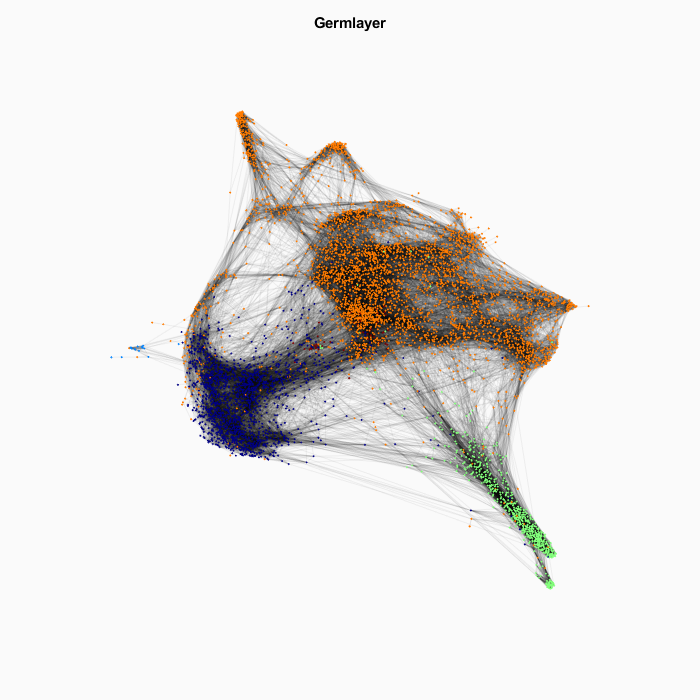

%%%%%%import cell_id_germ_6/8/10/13h.csv
%%%%%%add cell ID info
%A(1).celldata = cellidgerm6h
%A(2).celldata = cellidgerm8h
%A(3).celldata = cellidgerm10h
%A(4).celldata = cellidgerm13h

%A(1).celldata.Properties.VariableNames{1} = 'cell_IDs_names';
%A(1).celldata.Properties.VariableNames{2} = 'germ_layer';
%A(2).celldata.Properties.VariableNames{1} = 'cell_IDs_names';
%A(2).celldata.Properties.VariableNames{2} = 'germ_layer';
%A(3).celldata.Properties.VariableNames{1} = 'cell_IDs_names';
%A(3).celldata.Properties.VariableNames{2} = 'germ_layer';
%A(4).celldata.Properties.VariableNames{1} = 'cell_IDs_names';
%A(4).celldata.Properties.VariableNames{2} = 'germ_layer';

%%%%%plot by germlayer
%for j = 1:height(G.Nodes)
   %sample = G.Nodes{j,4}
   %cell = G.Nodes{j,3}
    %info = A(sample).celldata{cell,2}
    %G.Nodes{j,5} = info
%end

G.Nodes.Properties.VariableNames{5} = 'germ_layer';
stitch_plot_graph_germlayer(G, XY)

h = figure(6)

h =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [1 1 1]
    Position: [100 100 600 600]
       Units: 'pixels'

  Show all properties


set(h,'Position',[100 100 500 600])
print(h, 'timecourse_regnor_germlayer.png', '-dpng', '-r600')
print(h, 'timecourse_regnor_germlayer.pdf', '-dpdf', '-r600')
savefig(h, 'timecourse_regnor_germlayer.fig')

## (10) export

stitch_export('./wt_timecourse_prefiltered-SCT-STITCH/', A, G, XY, gene_names_all)